%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path


clearvars %clear all variables

# ODE Implosion

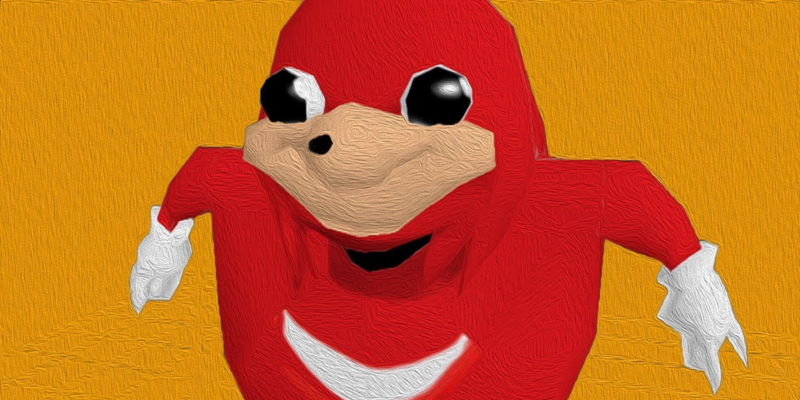

**Imploder ODE's på formen:**

syms y(t) x(t)

displayFormula([string(diff(x)), "'= k1(x) + k2(y) + k3'"]);

$$\frac{\partial }{\partial t}x\left(t\right){\mathrm{= k1(x) + k2(y) + k}}_{3}$$

displayFormula([string(diff(y)), "'= k4(x) + k5(y) + k6'"]);

$$\frac{\partial }{\partial t}y\left(t\right){\mathrm{= k4(x) + k5(y) + k}}_{6}$$

k = [-3 6 6 1 -4 -2]; % Eksempel input: '1 2 0 3 4 0' => k1=1, k2=2, k3=0, k4=3, k5=4, k6=0
 

**ODE's**

displayFormula([string(diff(x)), "' = '", string(k(1)*(x) + k(2)*(y) + k(3))]);

$$\frac{\partial }{\partial t}x\left(t\right)=6\,y\left(t\right)-3\,x\left(t\right)+6$$

displayFormula([string(diff(y)), "' = '", string(k(4)*(x) + k(5)*(y) + k(6))]);

$$\frac{\partial }{\partial t}y\left(t\right)=x\left(t\right)-4\,y\left(t\right)-2$$

**Higher Order Implosion**

HigherOrder = diff(y,2) - diff(y)*(k(1)+k(5))-y*(k(2)*k(4)-k(5)*k(1)) == k(2)*k(6)-k(5)*k(3);
disp(HigherOrder);

$$\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+7\,\frac{\partial }{\partial t}y\left(t\right)+6\,y\left(t\right)=12$$


solveEqn = dsolve(HigherOrder)

$$solveEqn = C_{2}\,{\mathrm{e}}^{-t}+C_{1}\,{\mathrm{e}}^{-6\,t}+2$$

%ans blir 2